# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 02-May-2024 20:12:02

## Create Array of Layers

layers = [
    imageInputLayer([128 128 1],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([2 2],"Name","maxpool","Padding","same")
    batchNormalizationLayer("Name","batchnorm")
    convolution2dLayer([3 3],64,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    flattenLayer("Name","flatten")
    fullyConnectedLayer(512,"Name","fc")
    reluLayer("Name","relu_4")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(4,"Name","fc_1")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot Layers

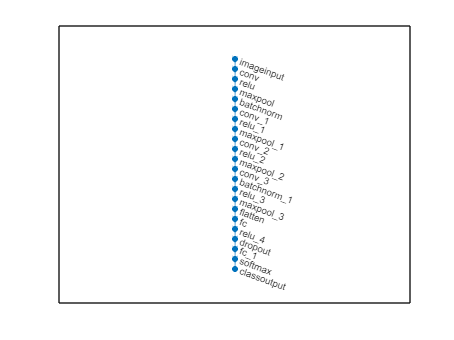

plot(layerGraph(layers));